### Load relevant information

TF_of_interest = 'CTCF';
[pwm_matrix, TF_binding_length] = getPWM(TF_of_interest);

pwmatrix =     0.0540    0.0240    0.0680    0.0420         0    0.2620    0.0040         0    0.0320    0.2660    0.0200    0.0800    0.0100    0.0260    0.1260
    0.3180    0.6460    0.0420    0.7900    0.9940    0.6660    0.6180    0.9980    0.0640    0.0900    0.3440    0.1940    0.0020    0.0660    0.5940
    0.5660    0.0240    0.7920    0.0620         0    0.0460    0.0020    0.0020    0.0080    0.5640    0.6200    0.0440    0.9760    0.8400    0.0740
    0.0620    0.3060    0.0980    0.1060    0.0060    0.0260    0.3760         0    0.8960    0.0800    0.0160    0.6820    0.0120    0.0680    0.2060


TF_binding_length

TF_binding_length = 15

padding = 10; % extra bases on sides of binding regions

load("CTCF_sequences")
% load("false_sequences")

num_TFs = length(sequences)

num_TFs = 158004

load("pentamer_shape_dict")
load("pentamers")
pentamers_dict = cellstr(pentamers)

pentamers_dict = 544×1 cell array
    {'AAAAA'}
    {'AAAAC'}
    {'AAAAG'}
    {'AAAAT'}
    {'AAACA'}
    {'AAACC'}
    {'AAACG'}
    {'AAACT'}
    {'AAAGA'}
    {'AAAGC'}
    {'AAAGG'}
    {'AAAGT'}
    {'AAATA'}
    {'AAATC'}
    {'AAATG'}
    {'AAATT'}
    {'AACAA'}
    {'AACAC'}
    {'AACAG'}
    {'AACAT'}
    {'AACCA'}
    {'AACCC'}
    {'AACCG'}
    {'AACCT'}
    {'AACGA'}
    {'AACGC'}
    {'AACGG'}
    {'AACGT'}
    {'AACTA'}
    {'AACTC'}


### Initialize shape data array

shapes = repmat([0], num_TFs, TF_binding_length+(2*padding) - 4, 4);
shapes(1, 1, :)

ans = ans(:,:,1) =

     0


ans(:,:,2) =

     0


ans(:,:,3) =

     0


ans(:,:,4) =

     0


### Normalize shape dictionary

MGW_col = pentamer_shape_dict(:, 1)

MGW_col =     3.3800
    4.0500
    3.6800
    3.6300
    4.6500
    4.0600
    4.4300
    3.8500
    4.0200
    4.0300


MGW_col = MGW_col - min(MGW_col)

MGW_col =     0.5300
    1.2000
    0.8300
    0.7800
    1.8000
    1.2100
    1.5800
    1.0000
    1.1700
    1.1800


MGW_col = MGW_col / max(MGW_col)

MGW_col =     0.1721
    0.3896
    0.2695
    0.2532
    0.5844
    0.3929
    0.5130
    0.3247
    0.3799
    0.3831



Roll_col = pentamer_shape_dict(:, 2)

Roll_col =    -5.0900
   -4.8000
   -6.4700
   -5.1200
   -2.8900
   -4.6500
   -3.2700
   -5.4900
   -3.2100
   -3.9500


Roll_col = Roll_col - min(Roll_col)

Roll_col =     3.4800
    3.7700
    2.1000
    3.4500
    5.6800
    3.9200
    5.3000
    3.0800
    5.3600
    4.6200


Roll_col = Roll_col / max(Roll_col)

Roll_col =     0.2060
    0.2232
    0.1243
    0.2043
    0.3363
    0.2321
    0.3138
    0.1824
    0.3173
    0.2735



ProT_col = pentamer_shape_dict(:, 3)

ProT_col =   -16.5100
  -14.4700
  -14.6800
  -14.8900
  -13.0500
  -12.4100
  -13.1500
  -12.7800
  -10.7100
  -10.5800


ProT_col = ProT_col - min(ProT_col)

ProT_col =          0
    2.0400
    1.8300
    1.6200
    3.4600
    4.1000
    3.3600
    3.7300
    5.8000
    5.9300


ProT_col = ProT_col / max(ProT_col)

ProT_col =          0
    0.1238
    0.1110
    0.0983
    0.2100
    0.2488
    0.2039
    0.2263
    0.3519
    0.3598



HelT_col = pentamer_shape_dict(:, 4)

HelT_col =    38.0100
   36.9500
   37.1800
   37.6800
   35.2200
   36.2000
   35.4800
   36.8600
   33.1800
   32.8100


HelT_col = HelT_col - min(HelT_col)

HelT_col =     7.0700
    6.0100
    6.2400
    6.7400
    4.2800
    5.2600
    4.5400
    5.9200
    2.2400
    1.8700


HelT_col = HelT_col / max(HelT_col)

HelT_col =     0.9944
    0.8453
    0.8776
    0.9480
    0.6020
    0.7398
    0.6385
    0.8326
    0.3150
    0.2630



shape_dict_normalized = [MGW_col Roll_col ProT_col HelT_col]

shape_dict_normalized =     0.1721    0.2060         0    0.9944
    0.3896    0.2232    0.1238    0.8453
    0.2695    0.1243    0.1110    0.8776
    0.2532    0.2043    0.0983    0.9480
    0.5844    0.3363    0.2100    0.6020
    0.3929    0.2321    0.2488    0.7398
    0.5130    0.3138    0.2039    0.6385
    0.3247    0.1824    0.2263    0.8326
    0.3799    0.3173    0.3519    0.3150
    0.3831    0.2735    0.3598    0.2630


### Get Shape Data

loading = waitbar(0,'Please wait...');
for i=1:num_TFs
% for i=21000:21000
    r = i/num_TFs;
    waitbar(r,loading,string(r));

%     for k = 1:1
    for k = 1:TF_binding_length+(2*padding) - 4
        r = extractBetween(sequences(i, 1),k,k+4);
        r = string(r);
        pos = find(pentamers_dict == r);
        if pos
            shapes(i, k, :) = shape_dict_normalized(pos, :);
        else
            pos = find(pentamers_dict == reverse(r));
            if pos
                shapes(i, k, :) = shape_dict_normalized(pos, :);
            end
        end
    end
end
close(loading)

shapes(50000, :)

ans =     0.3896    0.4903    0.3896    0.5390    0.4805    0.9091    0.7565    0.7013    0.6071    0.7597    0.6786    0.6786    0.7955    0.7922    0.6234    0.7013    0.6753    0.6266    0.6104    0.7597    0.8149    0.8149    0.7597    0.6104    0.6266    0.7565    0.7045    0.7597    0.7890    0.6851    0.6851    0.2232    0.3298    0.2232    0.3446    0.3470    0.4784    0.3416    0.3991    0.3689    0.6217    0.4026    0.4026    0.6459    0.3878    0.3831    0.4713    0.3943    0.3458    0.3730


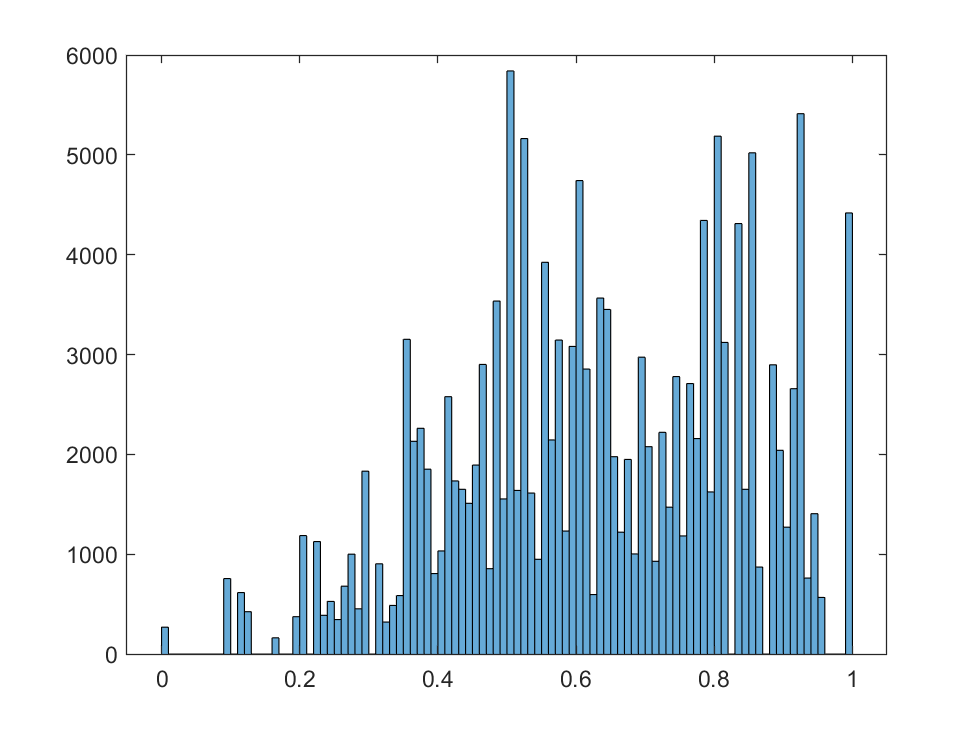

histogram(shapes(:, 1, 3))

save("CTCF_shapes", "shapes")
% save("CTCF_false_shapes", "shapes")